cameraman = imread('cameraman.tif');
spine = imread('spine.tif');

imageBrowser(fullfile(matlabroot, 'toolbox/images/imdata'))

folder = fileparts(which('spine.tif'))

folder = '/Users/chenbingcheng/Documents/MATLAB/RRY025_Image_processing/RRY025'

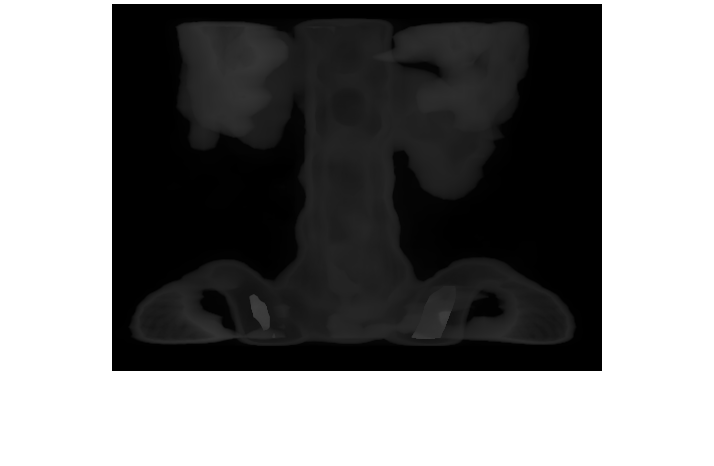

imshow(spine)

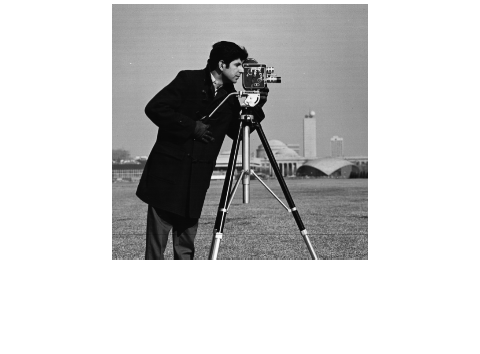

imshow(cameraman);

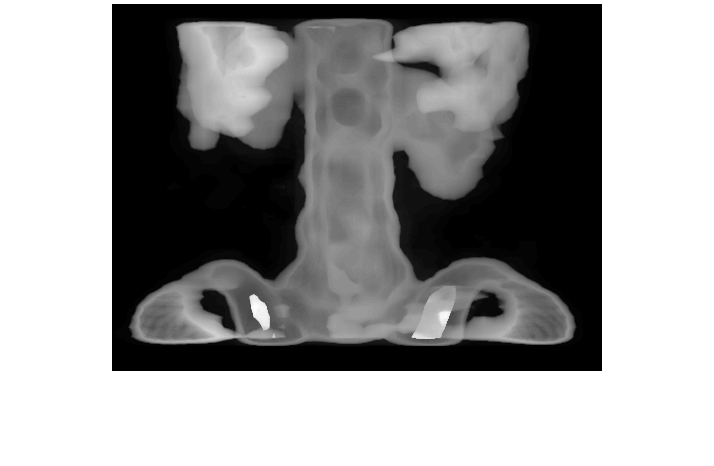

figure; 
imshow(spine, []);

imfinfo spine.tif

ans = struct with fields:
                     Filename: '/Users/chenbingcheng/Documents/MATLAB/RRY025_Image_processing/RRY025/spine.tif'
                  FileModDate: '08-Sep-2010 09:07:06'
                     FileSize: 69292
                       Format: 'tif'
                FormatVersion: []
                        Width: 490
                       Height: 367
                     BitDepth: 8
                    ColorType: 'indexed'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'RGB Palette'
                 StripOffsets: [8 289 4019 8116 12408 16005 19646 23350 26632 29577 31936 34376 36508 38024 39717 41397 43125 46361 50216 54920 60170 65751 67261]
              SamplesPerPixel: 1
                 RowsPerStrip: 16
              StripByteCounts: [281 3730 4097 4292 3597 3641 3704 3282 2945 2359 2

myimage = [0 1 2 3 4 ; 13 14 15 16 5 ; 12 19 18 17 6 ; 11 10 9 8 7];
whos myimage

  Name         Size            Bytes  Class     Attributes

  myimage      4x5               160  double              



class(myimage)

ans = 'double'

myimage_gray = mat2gray(myimage); 
myimage_gray

myimage_gray =          0    0.0526    0.1053    0.1579    0.2105
    0.6842    0.7368    0.7895    0.8421    0.2632
    0.6316    1.0000    0.9474    0.8947    0.3158
    0.5789    0.5263    0.4737    0.4211    0.3684


myimage_uint8 = im2uint8(myimage_gray)

myimage_uint8 = 4×5 uint8 matrix
     0    13    27    40    54
   174   188   201   215    67
   161   255   242   228    81
   148   134   121   107    94


whos myimage_uint8

  Name               Size            Bytes  Class    Attributes

  myimage_uint8      4x5                20  uint8              



im2foub = im2double(myimage_uint8)

im2foub =          0    0.0510    0.1059    0.1569    0.2118
    0.6824    0.7373    0.7882    0.8431    0.2627
    0.6314    1.0000    0.9490    0.8941    0.3176
    0.5804    0.5255    0.4745    0.4196    0.3686


myimage_bw = im2bw(myimage_gray)

myimage_bw = 4×5 logical array
   0   0   0   0   0
   1   1   1   1   0
   1   1   1   1   0
   1   1   0   0   0


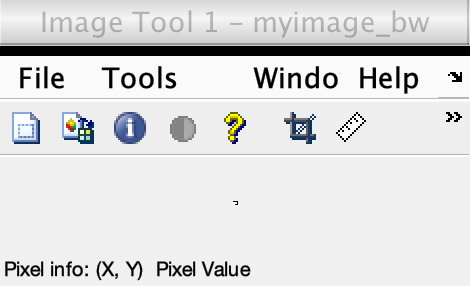

imtool(myimage_bw);

whos myimage_bw

  Name            Size            Bytes  Class      Attributes

  myimage_bw      4x5                20  logical              



myimage_bw_75 = im2bw(myimage_gray, 0.75)

myimage_bw_75 = 4×5 logical array
   0   0   0   0   0
   0   0   1   1   0
   0   1   1   1   0
   0   0   0   0   0


myimage_gray

myimage_gray =          0    0.0526    0.1053    0.1579    0.2105
    0.6842    0.7368    0.7895    0.8421    0.2632
    0.6316    1.0000    0.9474    0.8947    0.3158
    0.5789    0.5263    0.4737    0.4211    0.3684


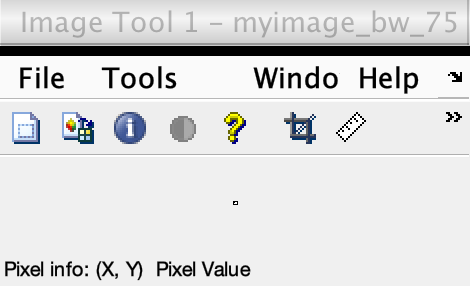

imtool(myimage_bw_75);

myimage_bw_75_double = im2double(myimage_bw_75)

myimage_bw_75_double =      0     0     0     0     0
     0     0     1     1     0
     0     1     1     1     0
     0     0     0     0     0


whos myimage_bw_75_double

  Name                      Size            Bytes  Class     Attributes

  myimage_bw_75_double      4x5               160  double              



whos myimage_bw_75

  Name               Size            Bytes  Class      Attributes

  myimage_bw_75      4x5                20  logical              



imwrite(myimage_gray, 'myimage.tif')

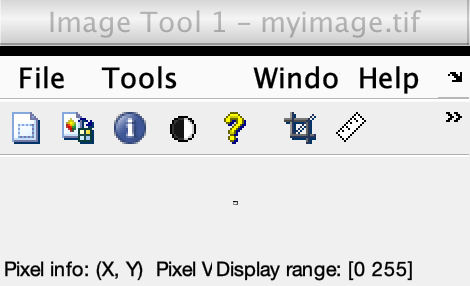

imtool('myimage.tif');

 myvector1 = [1 3 5 7 9 11 13]; myvector1

myvector1 =      1     3     5     7     9    11    13


 myvector2 = myvector1'

myvector2 =      1
     3
     5
     7
     9
    11
    13


myvector1(1:3)

ans =      1     3     5


myvector1(3:end)

ans =      5     7     9    11    13


myvector1([2 4 5])

ans =      3     7     9


myimage(2, 4)

ans = 16

myimage([4 2], [1 4 3])

ans =     11     8     9
    13    16    15


max(myimage(:))

ans = 19

A = [1 2 3; 4 5 6; 7 8 9] 

A =      1     2     3
     4     5     6
     7     8     9


B = A

B =      1     2     3
     4     5     6
     7     8     9


D = logical([1 0 0; 0 0 1; 0 0 0])

D = 3×3 logical array
   1   0   0
   0   0   1
   0   0   0


A(D)

ans =      1
     6


F=rand(2,4)

F =     0.3371    0.7943    0.5285    0.6020
    0.1622    0.3112    0.1656    0.2630


rand(5)

ans =     0.6541    0.2290    0.9961    0.0046    0.3998
    0.6892    0.9133    0.0782    0.7749    0.2599
    0.7482    0.1524    0.4427    0.8173    0.8001
    0.4505    0.8258    0.1067    0.8687    0.4314
    0.0838    0.5383    0.9619    0.0844    0.9106


xvec= linspace(-63,64,128);
yvec = linspace(-63,64,128);
[XX,YY] = meshgrid(xvec,yvec);

RR= sqrt(XX.^2 + YY.^2);

image_name = 'ngc6543a.jpg'; % image_name = 'football.jpg';
class(image_name)

ans = 'char'

index_start = 1; 
index_increment = 0.5; 
index_end = 4; 
for index = index_start:index_increment:index_end
    if mod(index, 1) == 0.5
        disp('The index is not a natural number');
    else
        disp('The index is a natural number');
    end 
end

The index is a natural number


The index is not a natural number


The index is a natural number


The index is not a natural number


The index is a natural number


The index is not a natural number


The index is a natural number


a = 10;
while a > 0
    disp('a is still greater than zero')
    a = a - 1;
end

a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
a is still greater than zero
